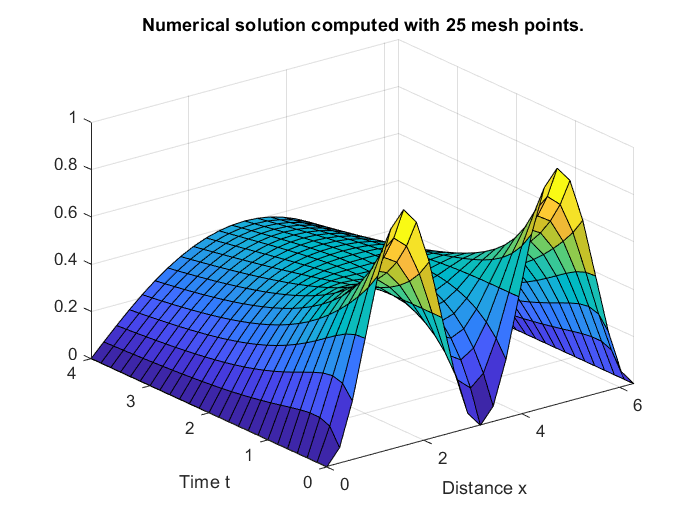

m = 0;
x = linspace(0,2*pi,25);
t = linspace(0,4,25);
sol = pdepe(m,@pdefun,@icfun,@bcfun,x,t);
% Extract the first solution component as u.
u = sol(:,:,1);
% A surface plot is often a good way to study a solution.
surf(x,t,u)
title('Numerical solution computed with 25 mesh points.')
xlabel('Distance x')
ylabel('Time t')

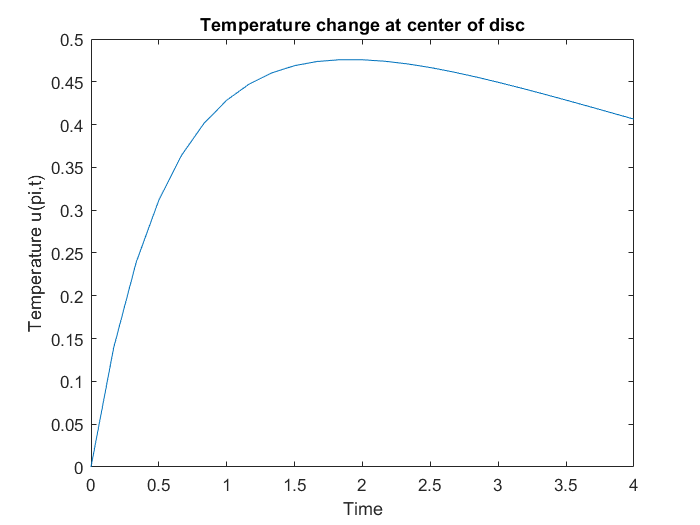

% A solution profile can also be illuminating half of array is 13.
figure
plot(t,u(:,13))
xlabel('Time')
ylabel('Temperature u(pi,t)')
title('Temperature change at center of disc')

% --------------------------------------------------------------

function [c,f,s] = pdefun(x,t,u,DuDx)
c = 2;
f = DuDx;
s = 0;
end
% --------------------------------------------------------------
function u0 = icfun(x)
u0 = sin(x)^2;
end
% --------------------------------------------------------------
function [pl,ql,pr,qr] = bcfun(xl,ul,xr,ur,t)
pl = ul;
ql = 0;
pr = ur;
qr = 0;
end